## Temperature Control Lab Activity

Vaccine production involves innoculating viral material within a host cuture. The viral meterial will denature if the temperature deviates from the setpoint at any given time for the incubation process. We will use the TCLab to simulate the incubator for the vaccine.

[Thematic Image]

To optimize the ammount of vacine produced, tune the PID to maximize time at the setpoint. First, simulate the TCLab unit and tune the parameters for the PID. Then, use the parameters from the simulation to control the temperature control lab at 40 C for 3 minutes, and 30 C for three minutes afterward.

[graph of setpoint]

## Simulation

#### PID Controller Equation


$$e(t) = SP - PV$$



$$u(t) = u_{bias} + K_ce(t) + \frac{K_c}{\tau_I}\int_0^te(t)dt-K_c\tau_D\frac{d(PV)}{dt}$$


Find values for $K_c$, $\tau_I$, and $\tau_D$ that minimize error in the simulation below.

clc; clear all; close all;
Kc = 0

Kc = 0

TauI = 0

TauI = 0

TauD =  0

TauD = 0

## Physical Verification

Verify your simulation by using the same parameters with the TCLab

Kc = 1

Kc = 1

tauI = 1

tauI = 1

tauD = 1

tauD = 1

arduino_sim()

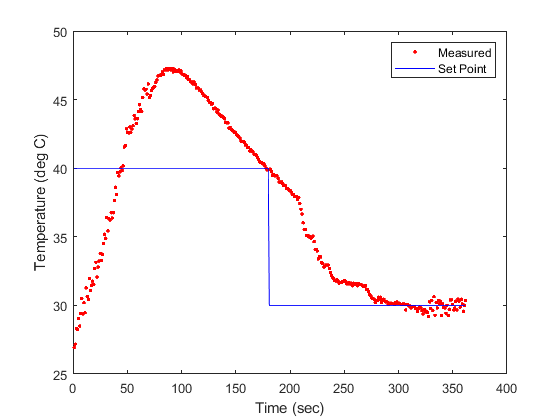

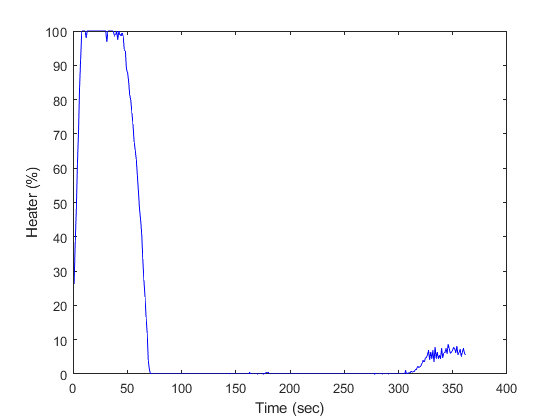

n = 60 * 6;

% initialize arrays
time = zeros(n);
setpoint = ones(n) * 40;
setpoint(180:end) = 30;
PV = zeros(n);
u = zeros(n);
error = zeros(n);
Ierror = 0;
prev_time = 0;

min = 0;
max = 100;

lab = tclab;
tic
for i = 1:n
    % timer
    while toc - prev_time <1
        pause(.01)
    end
    time(i) = toc;
    prev_time = time(i);
    
    % PID Controller
    PV(i) = lab.T1;
    e = setpoint(i) - PV(i);
    error(i) = e;
    Ierror = Ierror + e;
    if i ~= 1
        dPVdt = (PV(i) - PV(i-1)) / (time(i) - time(i-1));
    else
        dPVdt = 0;
    end
    
    P = Kc * e;
    I = Kc / tauI * Ierror;
    D = Kc * tauD * dPVdt;
    u(i) = P + I - D;
    
    % Anti-reset windup
    if u(i) > max
        u(i) = max;
        Ierror = Ierror - e;
    elseif u(i) < min
        u(i) = min;
        Ierror = Ierror - e;
    end
    
    % heater
    lab.Q1(u(i));
    
    % graph
    figure(1)
    plot(time(1:i), PV(1:i), 'r.')
    hold on;
    plot(time(1:i), setpoint(1:i), 'b-')
    hold on;
    xlabel('Time (sec)')
    ylabel('Temperature (deg C)')
    legend({'Measured', 'Set Point'})
    
    figure(2)
    plot(time(1:i), u(1:i), 'b-')
    xlabel('Time (sec)')
    ylabel('Heater (%)')
    hold off;
    
end